## **Code to simulate motion of Constant curvature section**

**Step 0: **Clear workspace and wipe console

clear
clc

**Step 1: **Load the necessary parameters of the CC section

l_nf = 1;
d = 0.04;
num_spacers = 10;
target_alpha = 90; % angle in degrees
start_alpha = 0; % angle in degrees
start_alpha_rad = deg2rad(start_alpha);
target_alpha_rad = deg2rad(target_alpha);

**Step 2: **Calculate the length of SMA and tip positions for angles starting from non-actuated state (0 degree) to target angle

alpha = linspace(start_alpha_rad, target_alpha_rad, 50);
s = linspace(0, 1, 50);

l_1_prime = zeros(1, length(alpha));
for i = 1:length(alpha)
    if alpha(i) == 0
        l_1_prime(i) = l_nf;
    else
        l_1_prime(i) = ((l_nf - (alpha(i)*d))*2*num_spacers*sin(alpha(i)/(2*num_spacers)))/alpha(i);
    end
end

% Calculate tip positions
tip_traj = zeros(length(l_1_prime), 2);
for i = 1:length(l_1_prime)
    T_packed = FKineSMA(l_1_prime(i), d, l_nf);
    tip_traj(i, 1) = T_packed.tip_position(1);
    tip_traj(i, 2) = T_packed.tip_position(2);
end

**Step 3: Plotting the motion**

- Plot the trajectory of the tip for reference

- Calculate the actual alpha achieved using l_1_prime and use this for subsequent plotting

- Calculate intermediate points along the backbone for plotting

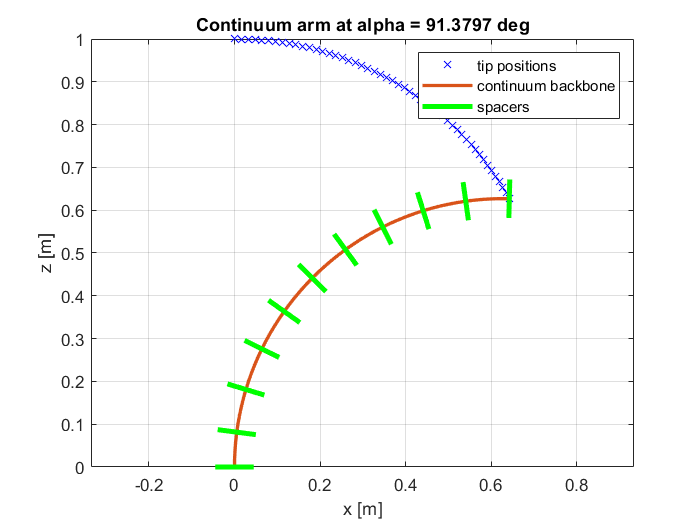

for i = 1:length(l_1_prime)
    % Wipe figure clean before each motion
    clf
    
    % Plot trajectory of the tip
    plot(tip_traj(:, 1), tip_traj(:, 2), 'bx')
    
    hold on
    
    alpha_act = (l_nf - l_1_prime(i))/d;    
    temp_points = zeros(length(s), 2);
    temp_angle = zeros(1, length(s));
    
    for j = 1:length(s)        
        T_packed = homogeneousTransformMatrix(s(j), alpha_act, l_nf);
        temp_points(j, 1) = T_packed.point_coord(1);
        temp_points(j, 2) = T_packed.point_coord(2);
        temp_angle(j) = T_packed.alpha;
    end
    % Plot current position of the arm
    plot(temp_points(:, 1), temp_points(:, 2),'LineWidth', 2)
    
    % Plot spacers
    spacer_location = length(s)/num_spacers;
    mid_point = zeros(1, 2);
    spacer_length = 0.3;
    for k = 0:num_spacers
        if k == 0
            mid_point(1) = 0;
            mid_point(2) = 0;
            spacer_x = [-0.5*spacer_length, 0.5*spacer_length]*spacer_length + mid_point(1);
            spacer_y = [0, 0] + mid_point(2);
        else
            mid_point(1) = temp_points(k*spacer_location, 1);
            mid_point(2) = temp_points(k*spacer_location, 2);
            spacer_x = [-0.5*spacer_length, 0.5*spacer_length]*spacer_length*cos(-temp_angle(k*spacer_location)) + mid_point(1);
            spacer_y = [-0.5*spacer_length, 0.5*spacer_length]*spacer_length*sin(-temp_angle(k*spacer_location)) + mid_point(2);
        end
        plot(spacer_x, spacer_y, 'LineWidth', 3, 'Color', 'green')
    end
    
    xlabel('x [m]')
    ylabel('z [m]')
    title(['Continuum arm at alpha = ', num2str(rad2deg(alpha_act)), ' deg'])
    legend('tip positions', 'continuum backbone', 'spacers')
    grid on
    axis equal
    
    % Force matlab to draw the plot for each frame
    drawnow
end